clc
clear all
close all

robot_name = '4R';
model = 'linear';
modality = '3D';
robot_path = strcat('saved_models/',robot_name,'/',model,'/',modality,'/matlab_files/');
addpath(robot_path)

robot = robot_3R;

robot =   rigidBodyTree with properties:

     NumBodies: 0
        Bodies: {1×0 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×0 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


load("dyn_mat.mat")

load("in_weights.mat")
load("in_bias.mat")

load("hidden_weights_1.mat")
load("hidden_bias_1.mat")

load("hidden_weights_2.mat")
load("hidden_bias_2.mat")

load("out_weights.mat")
load("out_bias.mat")

load("map_in_weights.mat")
load("map_in_bias.mat")

load("map_hidden_weights_1.mat")
load("map_hidden_bias_1.mat")

load("map_hidden_weights_2.mat")
load("map_hidden_bias_2.mat")

load("map_hidden_weights_3.mat")
load("map_hidden_bias_3.mat")

load("map_out_weights.mat")
load("map_out_bias.mat")

load("std.mat")

params = containers.Map;

params("map_in_weights") = map_in_weights;
params("map_in_bias") = map_in_bias;

params("map_hidden_weights_1") = map_hidden_weights_1;
params("map_hidden_bias_1") = map_hidden_bias_1;

params("map_hidden_weights_2") = map_hidden_weights_2;
params("map_hidden_bias_2") = map_hidden_bias_2;

params("map_hidden_weights_3") = map_hidden_weights_3;
params("map_hidden_bias_3") = map_hidden_bias_3;

params("map_out_weights") = map_out_weights;
params("map_out_bias") = map_out_bias;


%discrete time parameters
Ad = A;
Bd = B;

%continuous time parameters
delT = 0.005;
N = size(A,1); %lifted dimension
m= length(robot.gravityTorque); %number of controls
Ac = (A-eye(N))/delT;
Bc = B/delT;
Cc = C;
Cc_red = C(1:m,:);

%ZNN IMPLEMENTATION
path = "cardioid"

path = "cardioid"

% path = "lissajous"
% path = "curve2"
% path = "epicycloid"
c = 0.04;
T = 10;
n=1;
iterations = T/delT;
t_span = 0:delT:T;
lambda= diag([100,100,100,300,300,300]);

u_plus_og = 1*ones(m,1);
if standardize == 1
    u_plus = (u_plus_og - mean')./scale';
end
u_minus = -u_plus;
phi = diag(u_plus-u_minus);
u(:,1) = 0*ones(m,1);

chi(:,1) = log((u(:,1)-u_minus)./(u_plus-u(:,1)));

tic

%inverse map for cardioid path
theta_traced(:,1) = [pi/4;pi/4;-pi/4;-pi/4];

% theta_traced(:,1) = [1.9;0.8*pi;0.6*pi];%[0.1;pi/6;-pi/6];
% theta_traced(:,1) = 0*[1.9;0.6*pi;0.8*pi]; %cardioid
% theta_traced(:,1) = [-1.32444859; -0.74052581;  1.1733985]; %cardioid; %cardioid

% theta_traced(:,1) =  [0.2*pi;0.5*pi;-0.6*pi];

%initial position of the end effector
% hom_tf = getTransform(robot,theta_traced(:,1),'link_ee');


% % x_traced(:,1) = forward_map_3R(theta_traced(:,1),params); 
% 
% x_actual_traced(:,1) = forward_map_3R_real(theta_traced(:,1));
hom_tf = getTransform(robot,theta_traced(:,1),'link_ee');
if strcmp(modality,'2D')
    x_actual_traced(:,1) = hom_tf(1:2,4);
    [dummy,xd_dot(:,1),xd_ddot(:,1)] = paths(c,0, x_actual_traced(:,1),0, T, path);
    
    
    
else
    x_actual_traced(:,1) = hom_tf(1:3,4);
    [dummy,xd_dot(:,1),xd_ddot(:,1)] = path_3D(c,0, x_actual_traced(:,1),0, T, path);
    
end
x_traced(:,1) = x_actual_traced(:,1);
x_desired(:,1) = x_traced(:,1); %initial position of the end-effector same as desired position
x_traced_dot(:,1) = xd_dot(:,1);
theta_desired(:,1) = theta_traced(:,1);

W = Jacobian_map(theta_traced(:,1),params);
theta_dot_desired(:,1) = pinv(W)*xd_dot(:,1);
theta_dot_traced(:,1) = theta_dot_desired(:,1);

%lifting
states_traced(:,1) = [theta_traced(:,1);   % states consists of theta and theta_dot
                      theta_dot_traced(:,1)];

z(:,1) = lifting_3R(states_traced(:,1),encode_in_weights,encode_in_bias,encode_hidden_weights_1,encode_hidden_bias_1,encode_hidden_weights_2,encode_hidden_bias_2,encode_out_weights,encode_out_bias);
z_dot(:,1) = Ac*z(:,1)+Bc*u(:,1);

for i=1:iterations
    t = t_span(i);
    if strcmp(modality,'2D')
        [x_desired(:,i), xd_dot(:,i),xd_ddot(:,i)] = paths(c,pi/6, x_traced(:,1),t, T, path);
    else
        [x_desired(:,i), xd_dot(:,i),xd_ddot(:,i)] = path_3D(c,pi/6, x_traced(:,1),t, T, path);
    end
     
    error(:,i) = [x_traced(:,i); x_traced_dot(:,i)] - [x_desired(:,i); xd_dot(:,i)];

    %Jacobian parameters
    W = Jacobian_map(theta_traced(:,i),params);
    W_dot = Jacobian_map_dot(theta_traced(:,i),theta_dot_traced(:,i),params);
    
    J_tilde = [W zeros(size(W));
                W_dot W];

    psi = diag(exp(chi(:,i))./(1+exp(chi(:,i))).^2);

    
    z_dot(:,i)=Ac*z(:,i)+Bc*u(:,i);

    chi_dot = pinv(Bd*phi*psi)*(-Ad*z_dot(:,i) + pinv(J_tilde*Cc)*([xd_dot(:,i);xd_ddot(:,i)] - lambda*error(:,i)));


    if i<=3
        chi(:,i+1) = chi(:,i)+chi_dot*delT;
    % elseif i>2 && i<=3
    %     chi(:,i+1) = (2*delT*chi_dot+4*chi(:,i)-chi(:,i-1))/3;
    % elseif i>3
    %     chi(:,i+1) = (12*delT*chi_dot+36*chi(:,i)-4*chi(:,i-2))/32;
    % 
    %  end

    else %FIFD
        chi(:,i+1) = (8/5)*chi_dot*delT + (3/5)*chi(:,i) + (1/5)*chi(:,i-1)+ (1/5)*chi(:,i-2); %FIFD
    end

    u(:,i+1) = phi*(exp(chi(:,i+1))./(1+exp(chi(:,i+1))))+u_minus;
    
    if standardize == 1
        u(:,i) = (u(:,i).*scale') + mean';
    end

     th_ddot = forwardDynamics(robot,theta_traced(:,i),theta_dot_traced(:,i),u(:,i));
     theta_dot_traced(:,i+1) = theta_dot_traced(:,i) + th_ddot*delT;
     theta_traced(:,i+1) = theta_traced(:,i) + theta_dot_traced(:,i+1)*delT;

     % [theta_traced(:,i+1), theta_dot_traced(:,i+1)] = dynamics_3R(u(:,i),theta_traced(:,i),theta_dot_traced(:,i));
     states_traced(:,i+1) = [theta_traced(:,i+1);theta_dot_traced(:,i+1)];
     z(:,i+1) = lifting_3R(states_traced(:,i+1),encode_in_weights,encode_in_bias,encode_hidden_weights_1,encode_hidden_bias_1,encode_hidden_weights_2,encode_hidden_bias_2,encode_out_weights,encode_out_bias);

     
     x_traced(:,i+1) = forward_map_3R(theta_traced(:,i+1),params);
     x_traced_dot(:,i+1) = Jacobian_map(theta_traced(:,i+1),params)*theta_dot_traced(:,i+1);
     hom_tf = getTransform(robot,theta_traced(:,i+1),'link_ee');
     x_actual_traced(:,i+1) = hom_tf(1:length(x_actual_traced(:,1)),4);

     % x_actual_traced(:,i+1) = forward_map_3R_real(theta_traced(:,i+1));
end

% end_time = tic;
% time_taken = end_time-start_time
toc

Elapsed time is 6.083110 seconds.


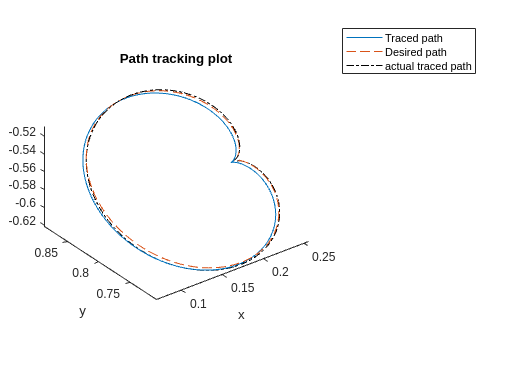

figure()
plot3(x_traced(1,:),x_traced(2,:),x_traced(3,:))
hold on
plot3(x_desired(1,:),x_desired(2,:),x_desired(3,:),"--")
hold on
plot3(x_actual_traced(1,:), x_actual_traced(2,:),x_actual_traced(3,:),"k-.")
xlabel("x")
ylabel("y")
title("Path tracking plot")
legend("Traced path","Desired path", "actual traced path")
axis("equal")
hold off

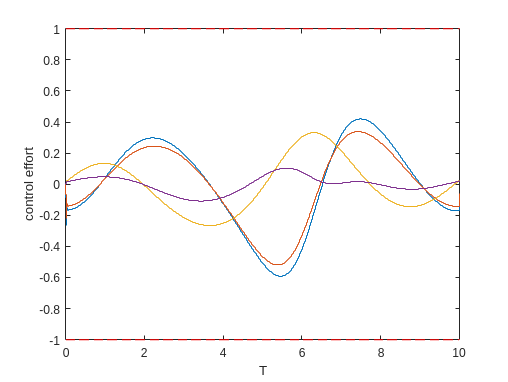

%plots
%control effort plot
figure()
for i = 1:m
 stairs(t_span(1:end),u(i,:))
 hold on
end
plot([0,T],[u_plus_og(1),u_plus_og(1)], 'r--' ,[0,T],[-u_plus_og(1),-u_plus_og(1)],'r--')
hold on
xlabel("T")
ylabel('control effort')
hold off

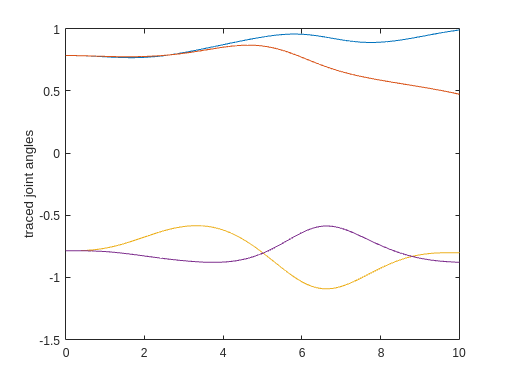

%states traced plot
figure()
for i  = 1:m
    plot(t_span,states_traced(i,:))
    hold on
end

ylabel('traced joint angles')
hold off

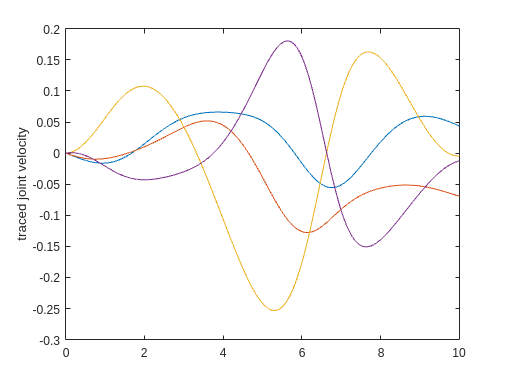

figure()
for i  = 1:m
    plot(t_span,states_traced(m+i,:))
    hold on
end

ylabel('traced joint velocity')
hold off

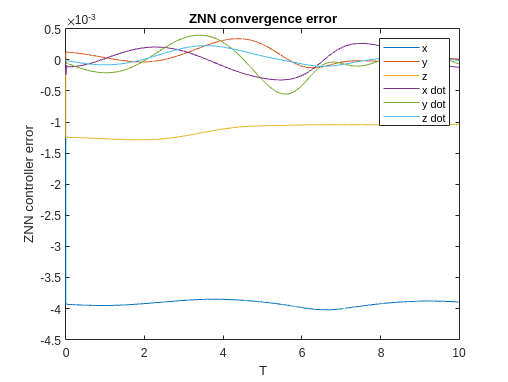

figure()
%error plot
plot(t_span(1:end-1),error)
xlabel('T')
ylabel("ZNN controller error")
legend("x","y", "z","x dot","y dot", "z dot")
title("ZNN convergence error")

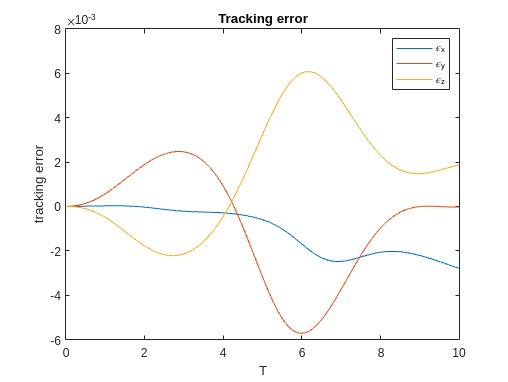

figure()
%error plot
tracking_error = x_desired-x_actual_traced(:,1:end-1);
plot(t_span(1:end-1),tracking_error)
xlabel('T')
ylabel("tracking error")
title("Tracking error")
legend("\epsilon_x","\epsilon_y","\epsilon_z")
hold off

%control effort required
u_norm = sum(vecnorm(u)*delT)

u_norm = 3.7515

%tracking error norm
tracking_error_norm = sum(vecnorm(x_desired-x_actual_traced(:,1:end-1))*delT)/T

tracking_error_norm = 0.0035

%tracking error norm
controller_error_norm = sum(vecnorm(error)*delT)/T

controller_error_norm = 0.0041